rng(0);
clear;

Download the dataset comprising images of handwritten digits in http://yann.lecun.com/exdb/ mnist; this has been downloaded in the folder “data” and stored as “mnist.mat”. As of now, for each digit, each 28 × 28 pixel image is represented using 282 coordinate values in the Euclidean space of dimension 282 . 

Suppose you decide to re-represent the images using only 84 coordinates (instead of 282 = 784) in a 84-dimensional basis for some 84-dimensional hyperplane within the original Euclidean space, such that the chosen 84-dimensional hyperplane maximizes the total dispersion of the original data (for the chosen digit) within the hyperplane. 

%see prev prob
load('../data/mnist.mat'); % code folder being pwd, change path otherwise
for i = (0:9)
    ddata = digits_train(:,:,labels_train==i);% taking images corresponding to label
    dig{i+1} = double(reshape(ddata,28*28,[]));% storing as an array as number of images of each digit may vary
end

covs = []; % all covs kept together
for i = (1:10)
    [sx,sy] = size(dig{i});
    dmean = sum(dig{i},2)/sy; %sample mean
    dcov = (dig{i}*(dig{i}'))/(sy-1) - sy*dmean*dmean'/(sy-1); %sample covariance
    covs = cat(3,covs,dcov);
end

• (5 points) Write a function to compute those 84 coordinates, for each of the ten digits (0–9). 


% example - on the first image of 0
xramg = dim_red(dig{1}(:, 1), 1, covs)

xramg = 1.0e+03 *

    0.4267
    1.2278
   -1.9327
    0.2373
    0.4875
    0.2615
   -0.1402
    0.0420
   -0.3433
   -0.1130


• (5 points) Give an algorithm for regenerating / reconstructing the image using those 84 bases (and the knowledge of the designed 84-dimensional basis). For each of the ten digits (0–9), pick an image, and show the original and the reconstructed images side by side.

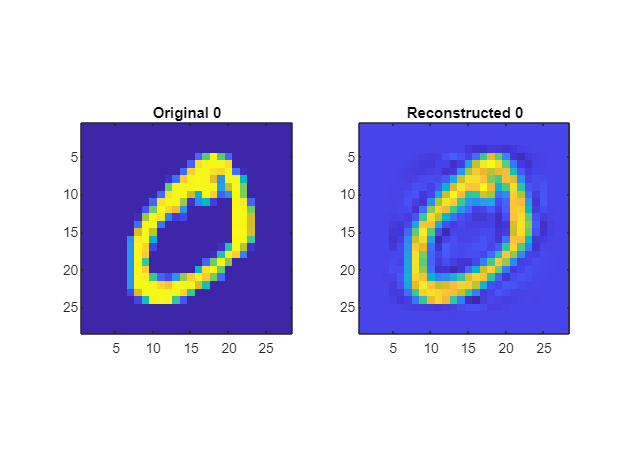

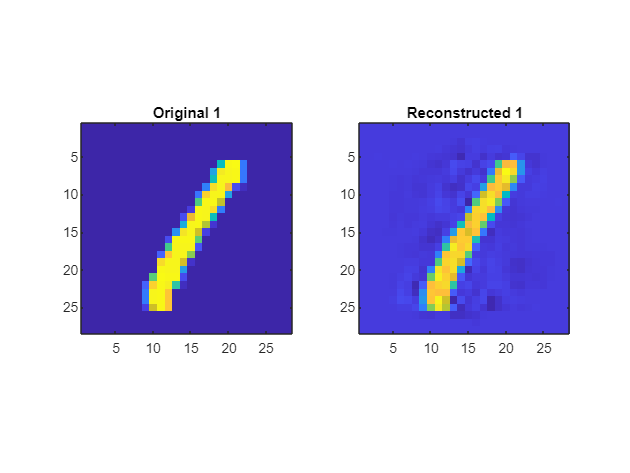

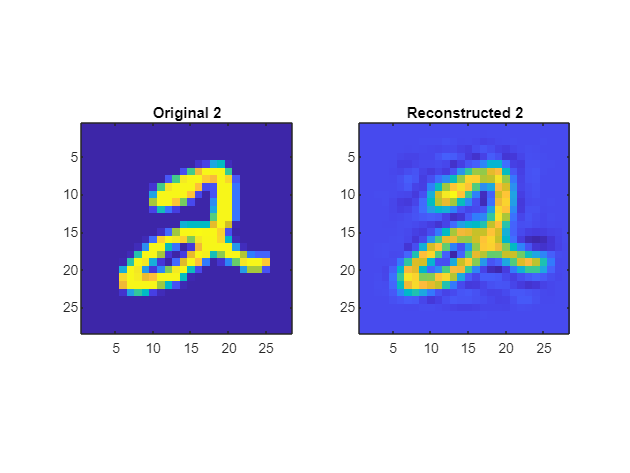

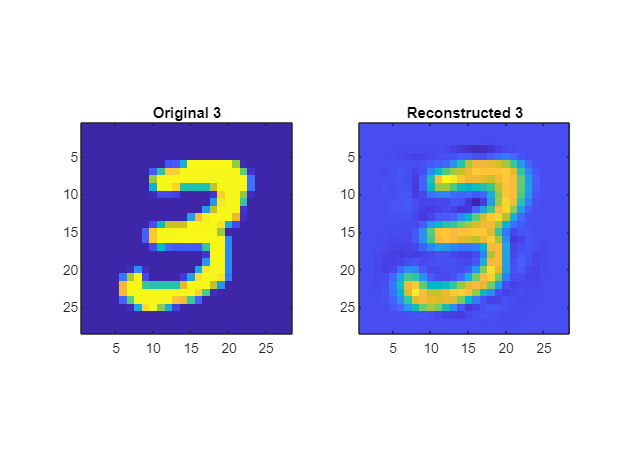

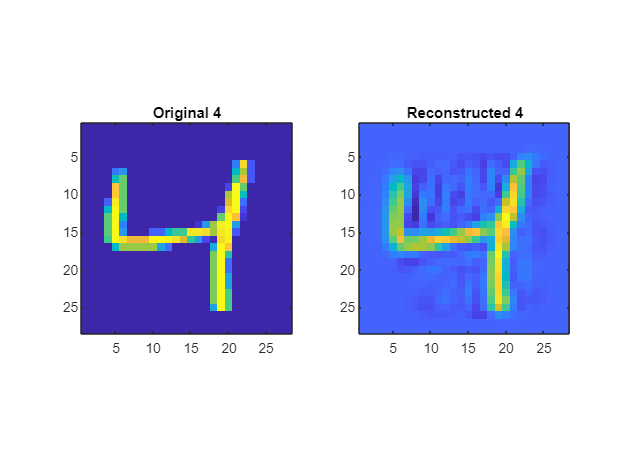

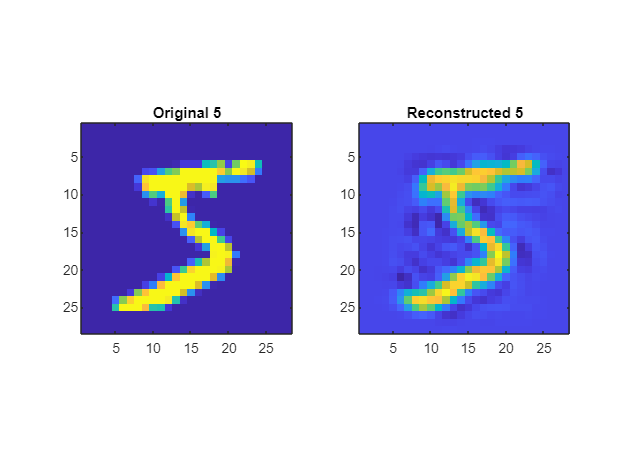

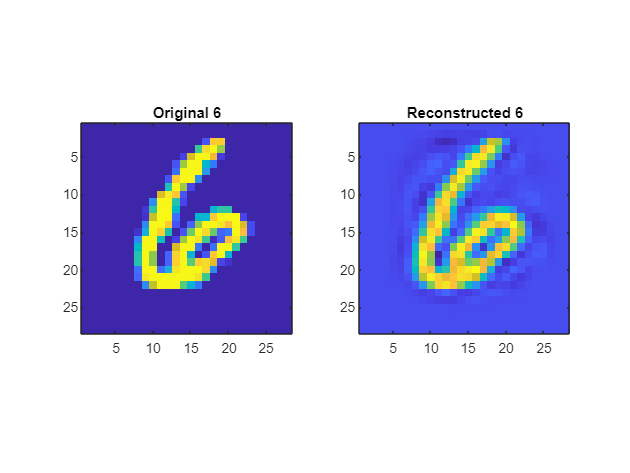

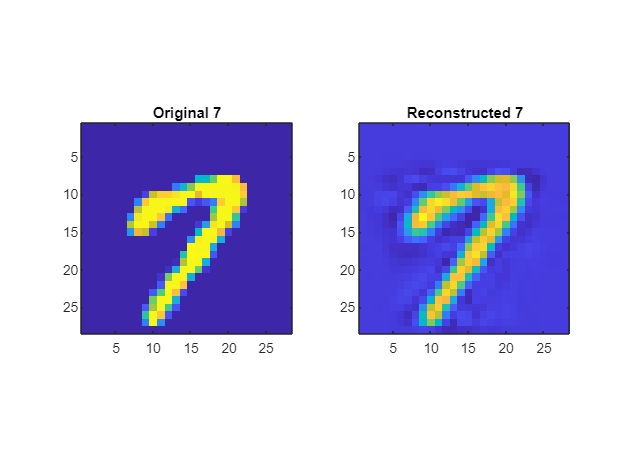

bases = deduce_basis(covs); % the basis aka 'Q'
for i = (1:10)

    img = dig{i}(:,1); % we pick the first image for the demo - aka 'w'

    % v = Q w
    recim = bases(:,:,i)*dim_red_with_basis(img,i,bases);

    figure,
    subplot(1,2,1);%old
    %nexttile    
    imagesc(reshape(img,28,28));
    title("Original "+(i-1));
    pbaspect([1,1,1]);
    subplot(1,2,2);%new
    %nexttile    
    imagesc(reshape(recim,28,28));
    title("Reconstructed "+(i-1));
    pbaspect([1,1,1]);
end

function red_coords = dim_red(vec, digit, covs)
%generating 84 coordinates from scratch, given covariance matrix
    [Q, ~] = eigs(covs(:, :, digit), 84); % getting the top 84 eigenvectors - basis
    red_coords = (Q')*vec;
end

function red_coords = dim_red_with_basis(vec,digit,basis)
%generating 84 coordinates given the bases
    red_coords = (basis(:,:,digit)')*vec;
end

% deducing the basis for each digit - as a 3D stacked matrix
% does not use eigs
function coords = deduce_basis(covs_tmp)
    coords=zeros(784,84,10);%784*84*10 matrix, for each digit along z axis
    for i =(1:10)
        [Q,D] = eig(covs_tmp(:,:,i));
        eigens = sort(diag(D),'descend');
        eigens = eigens(1:84);
        %return concatenated relevant coordinate vectors
        W = ismember(D,eigens); % diagonal matrix with relevant dimensions highlighted - see p4
        W(:,~any(W,1))=[];% removing empty columns
        V = Q*W; % transform
        coords(:,:,i) = V;%update
    end
end
